% Get the row and column coordinates for each pixel
N = 200;
[C,R] = meshgrid(0:N-1, 0:N-1);
disp('The first few values of the R array:')

The first few values of the R array:


R(1:3,1:3)

ans =      0     0     0
     1     1     1
     2     2     2


disp('The first few values of the C array:')

The first few values of the C array:


C(1:3,1:3)

ans =      0     1     2
     0     1     2
     0     1     2


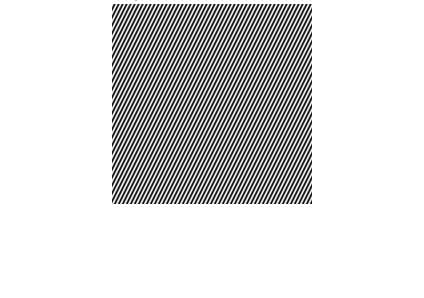


% Create a signal containing 2 sinusoids
wr =  0.25*pi; % digital freq in the row dimension
wc =  0.5 *pi; % digital freq in the col dimension
wr2 = 0.25*pi; % digital freq in the row dimension
wc2 = 0.5*pi; % digital freq in the col dimension
I = uint8(128 + 60*cos(wr*R+wc*C) + 60*cos(wr2*R+wc2*C));
imshow(I)
title('Image with 2 Sinusoids')

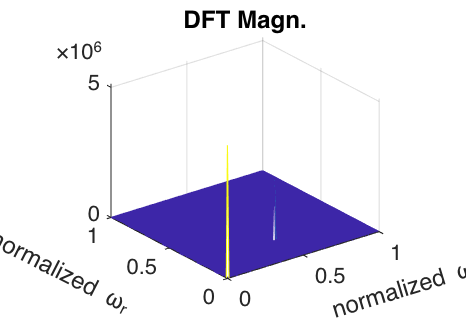


% Compute DFT of the image
F = fft2(I,N,N);
F = abs(F);
F = F(1:N/2+1,1:N/2+1); % Just keep the region from w = 0 to pi

% Mesh plot of the DFT magnitude
k = 0:N/2;
wnorm = k/(N/2);
mesh(wnorm,wnorm,F)
title('DFT Magn.')
xlabel('normalized \omega_c','Rotation',17)
ylabel('normalized \omega_r','Rotation',-27)


% Remove the zero-freq component so we can see the other peaks better
F(1:3,1:3) % There's a huge value at zero freq due to the constant 128 in the signal.

ans =      5120000           0           0
           0           0           0
           0           0           0


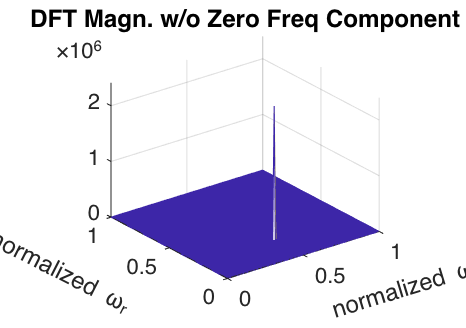

F(1,1) = 0; % Set to zero at zero freq so we can see the other peaks better

% Mesh plot of the DFT magn w/o zero freq component
mesh(wnorm,wnorm,F)
title('DFT Magn. w/o Zero Freq Component')
xlabel('normalized \omega_c','Rotation',17)
ylabel('normalized \omega_r','Rotation',-27)

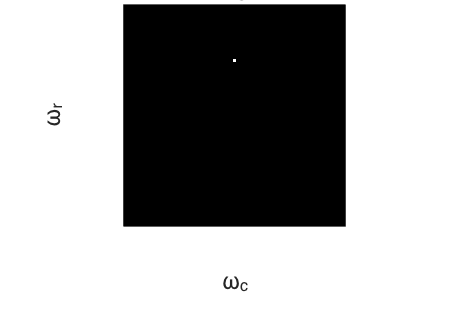


% 2D plot of the DFT magnitude
imshow(rescale(F),'InitialMagnification',200)
title('DFT Magnitude')
xlabel('\omega_c')
ylabel('\omega_r')